# 最短路径

引用：https://www.bilibili.com/video/BV1Rq4y1S7S8?p=29&spm_id_from=pageDriver

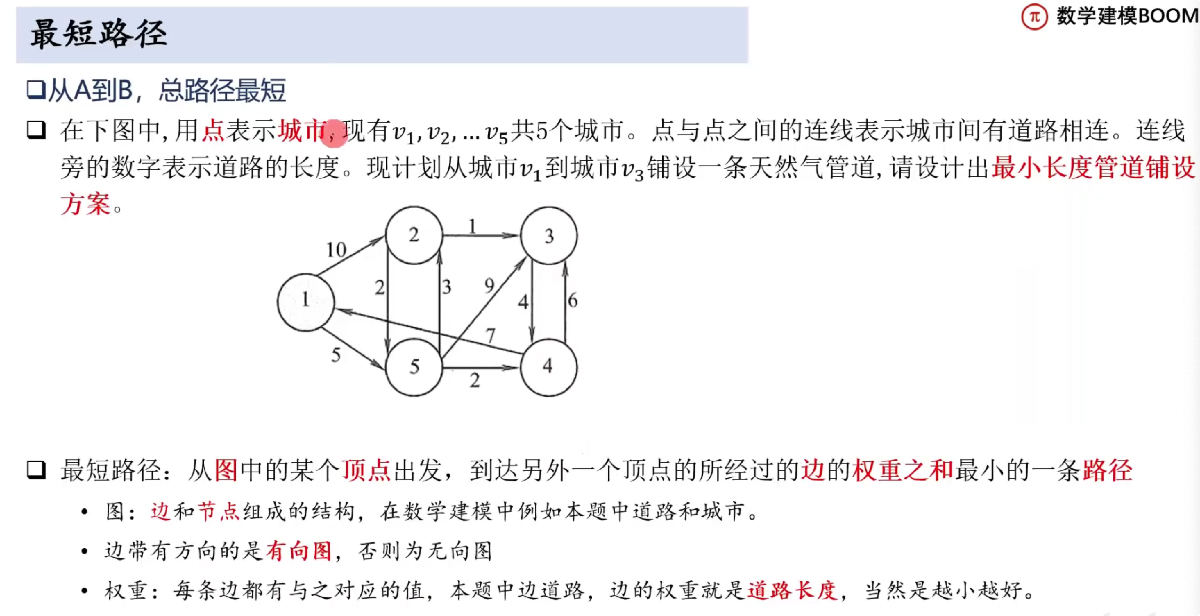

## 1. 稀疏矩阵和权值

`sparse()` - 生成稀疏矩阵，也就是除了注明的几个元素之外其他的都是 0

`W` -  表示每条稀疏矩阵对应路径权值

`DG` - 稀疏矩阵和权值

W = [10 5 2 1 4 6 7 3 9 2]

DG = sparse( ...
    [1 1 2 2 3 4 4 5 5 5], ...
    [2 5 5 3 4 3 1 2 3 4], ...
    W)

## 2.【函数】求最短路径：

[dist, path, pred] = graphshortestpath(稀疏矩阵和权值, 起始节点, 结束节点)

dist - 最短路径的值

path - 最短路径经过的节点

pred - 

[dist, path, pred] = graphshortestpath(DG, 1, 3)

biograph 生成图对象

view 显示该图

point_name = ["城市 1", "城市 2", "城市 3", "城市 4", "城市 5"];
h = view(biograph(DG, point_name, "ShowWeights", "on"))

将最短路径的节点和边缘标记为红色并增加线宽：

`getedgesbynodeidt` 得到图h的指定边的句柄

- 第一个参数是图

- 第二个是边的出点

- 第三个是边的入点句柄确保能找到对应的东西

get 查询图的属性，h. Nodes(path)，'ID' 得到图h中最短路径的

set函数设置图形属性

edges = getedgesbynodeid(h, get(h.Nodes(path), 'ID'));
set(edges, 'LineColor', [1 0 0])  % 第二个参数是：RGB 数值
set(edges, 'LineWidth', 2)

## 【例题】2

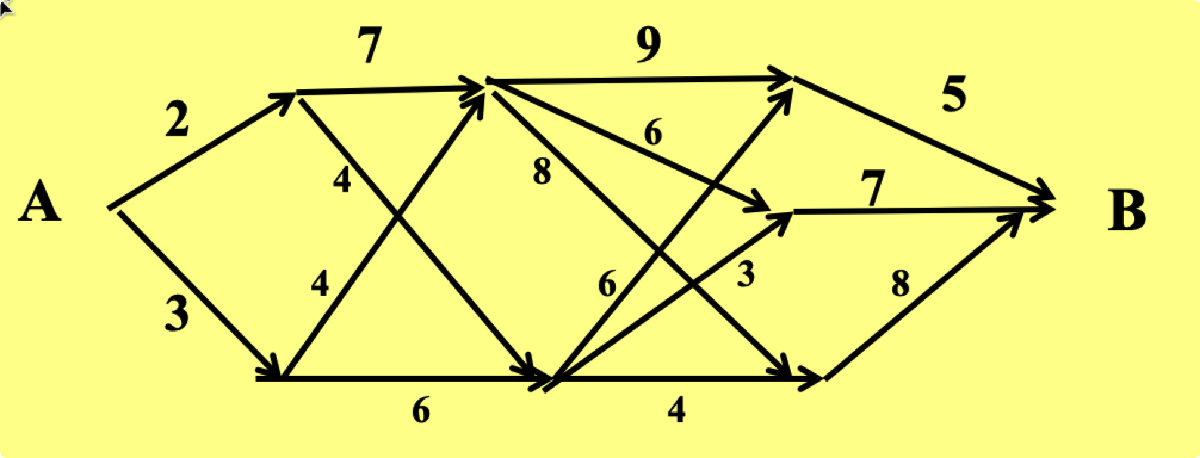

% 因为 DG 必须为方阵，所以另加了一个 9-1 的节点但路径为 0
W2 = [2 3 7 4 4 6 9 6 8 6 3 4 5 7 8 0]

W2 =      2     3     7     4     4     6     9     6     8     6     3     4     5     7     8     0



DG2 = sparse( ...
    [1 1 2 2 3 3 4 4 4 5 5 5 6 7 8 9], ...
    [2 3 4 5 4 5 6 7 8 6 7 8 9 9 9 1], ...
    W2)

DG2 =    (1,2)        2
   (1,3)        3
   (2,4)        7
   (3,4)        4
   (2,5)        4
   (3,5)        6
   (4,6)        9
   (5,6)        6
   (4,7)        6
   (5,7)        3
   (4,8)        8
   (5,8)        4
   (6,9)        5
   (7,9)        7
   (8,9)        8



[dist2, path2, pred2] = graphshortestpath(DG2, 1, 9)

dist2 = 16

path2 =      1     2     5     7     9


pred2 =      0     1     1     3     2     5     5     5     7


【例题】2

% 因为 DG 必须为方阵，所以另加了一个 9-1 的节点但路径为 0
DG3 = sparse( ...
    [1 1 1 2 3 3 4 4 4 4 5  5  5 6  7  7  8 8  8 9  10 10 11 12], ...
    [2 3 4 3 5 6 6 7 8 9 10 7  6 11 10 11 7 12 9 12 12 11 12 1], ...
    [2 5 7 8 3 1 3 4 1 6 6  10 2 6  1  1  4 5  8 3  4  5  2  0])

DG3 =    (1,2)        2
   (1,3)        5
   (2,3)        8
   (1,4)        7
   (3,5)        3
   (3,6)        1
   (4,6)        3
   (5,6)        2
   (4,7)        4
   (5,7)       10
   (8,7)        4
   (4,8)        1
   (4,9)        6
   (8,9)        8
   (5,10)       6
   (7,10)       1
   (6,11)       6
   (7,11)       1
  (10,11)       5
   (8,12)       5
   (9,12)       3
  (10,12)       4
  (11,12)       2



[dist3, path3, pred3] = graphshortestpath(DG3, 1, 12)

dist3 = 13

path3 =      1     4     8    12


pred3 =      0     1     1     1     3     3     4     4     4     7     6     8


【例题】3

% 因为 DG 必须为方阵，所以另加了一个 9-1 的节点但路径为 0
DG4 = sparse( ...
    [1 1 1 2 2 3 3 4 4 5 5 5 6 6 6 7 8 9 10 ], ...
    [2 3 4 5 6 5 6 5 6 7 8 9 7 8 9 10 10 10 1], ...
    [4 3 1 6 3 4 7 5 6 11 4 3 9 6 8 6 4 5 0])

DG4 =    (1,2)        4
   (1,3)        3
   (1,4)        1
   (2,5)        6
   (3,5)        4
   (4,5)        5
   (2,6)        3
   (3,6)        7
   (4,6)        6
   (5,7)       11
   (6,7)        9
   (5,8)        4
   (6,8)        6
   (5,9)        3
   (6,9)        8
   (7,10)       6
   (8,10)       4
   (9,10)       5



[dist3, path3, pred3] = graphshortestpath(DG4, 1, 10)

dist3 = 14

path3 =      1     4     5     8    10


pred3 =      0     1     1     1     4     2     6     5     5     8
